%% Perform simulations for mixed traffic with human-drivan vehicles and ccc with delay
clear; %close all; clc;

%% Parameters
% number of vehicles
veh_num=3;
% distribution of ccc and human driven vehicles
driver=cell(1,veh_num);
driver(:)={'human'};            % all vehicles are human driven
driver(3)={'ccc'};    % replace human driven vehicles with ccc

% type of ccc vehicle
vehtype='car';
% vehtype='truck';

% vehicle parameters
if strcmp(vehtype,'car')	% personal vehicle
    k=0.45;     % air drag
    m=1500;     % mass
    amin=8;     % max deceleration
    amax=3;     % max acceleration
    P=75000;	% max power
    l = 4.5;
else	% truck
    k=3.85;     % air drag
    m=29500;	% mass
    amin=4;     % max deceleration
    amax=2;     % max acceleration
    P=300000;	% max power
end

% gravitational constant
g=9.81;

% saturation function
sat=@(u)(u<-amin).*(-amin)+(-amin<=u & u<=amax).*u+(amax<u).*amax;


% ccc parameters
% control gains
% ki=0.0;
% kv=0.5;
% kp=0.8;
alpha01=0.4;
beta01=0.2;
beta02=0;
beta03=0;

% delay
sigma=0.6;
% range policy parameters
kappa0=0.6;
hst=5;
hgo=55;
vstar=20;
h0star=hst+vstar/kappa0;

% human driver parameters
% control gains
alphah=0.2;
betah=0.6;
% delay
tau=1;

% range policy parameters
vmax=30;
% hgo=hst+vmax/kappa;
% equilibrium velocity and headway
syms h;
eq = vmax*(2*hgo - hst - h)*(h - hst)/(hgo - hst)^2 == vstar;
S = solve(eq,h);
h1star = min(eval(S));
h2star = h1star;
kappah= 2*vmax*(hgo - h1star)/(hgo - hst)^2;

% range policy
Vh=@(h)vmax.*(hgo<=h) + (vmax*(2*hgo - hst - h).*(h-hst)/(hgo-hst)^2).*(hst<h & h<hgo);
V0=@(h)vmax*(hgo<=h)+kappa0*(h-hst).*(hst<h & h<hgo);
W=@(vL)vmax*(vmax<=vL)+vL.*(vL<vmax);
uccc=@(h0,v0,v1,v2,v3)alpha01*(V0(h0)-v0)+beta01*(W(v1)-v0)...
                    +beta02*(W(v2)-v0)+beta03*(W(v3)-v0);
uh=@(hi,vi,vip1)alphah*(Vh(hi)-vi)+betah*(vip1-vi);

% right-hand side of equations for ccc vehicle
ccc=@(t,x,xdelay,vL,vLdelay,v1delay,v2delay,sat,uccc)...
    [vL(t)-x(2);...
    sat(uccc(xdelay(1),xdelay(2),v1delay(t),v2delay(t),vLdelay(t)))];
    
% right-hand side of equations for human driven vehicle
human=@(t,x,xdelay,vL,vLdelay,sat,uh)...
    [vL(t)-x(2);...
    sat(uh(xdelay(1),xdelay(2),vLdelay(t)))];

% initial condition - history for ccc vehicle
cccinit=@(t)[h0star;vstar];
% initial condition - history for human driven vehicle
humaninit=@(t)[h1star;vstar];

% regions for plotting
hminplot=0;
hmaxplot=60;
vminplot=0;
vmaxplot=30;

% time
t0=0;
tend=100;
deltat=0.01;

% piecewise linear function with following points
% leader velocity
% vamp=6;
% om=0.5;
% vLead=@(t)vstar+vamp*sin(om*t);

vL0=vstar;
aunderbar = 1;
abar = 0.5;
t1=10;
t2=30;
t3=tend;

% leader velocity values at these time instants

% load('20170730_114049_8_vehicles','vel');
% vLead = vel{1};
% vLeadtau=(time<t0+tau).*vstar+...
%               (t0+tau<=time).*interp1(time,vLead,time-tau,'linear','extrap');
% sLead = vLead.*time;

vLead=@(time)(t0<=time & time<t1).*(vL0-aunderbar*time)+...
      (t1<=time & time<t2).*(vL0+abar*(time-t2))+...
      (t2<=time & time<=t3).*(vL0);
sLead = @(time)(t0<=time & time<t1).*(vL0-aunderbar*time).*time+...
      (t1<=time & time<t2).*(vL0+abar*(time-t2)).*time+...
      (t2<=time & time<=t3).*(vL0).*time;
  
  
% delayed leader velocity values
% vLeadtau=@(time,delay)(time<t0+delay).*vL0+...
%       (t0+delay<=time).*interp1(time,vLead,time-delay,'linear','extrap');




%% Simulation
% simulation time
hist=t0-sigma:deltat:t0;	% time of history (initial conditions)
time=t0:deltat:tend;	% simulation time


% simulate the motion of each vehicle one by one


hFollow=zeros(veh_num,length(time));
vFollow=zeros(size(hFollow));
sFollow=zeros(size(hFollow));
for kveh=1:veh_num
    disp(['Simulation of vehicle #',num2str(kveh)]);
    % pick initial condition and model for ccc or human driven vehicle
    if strcmp(driver{kveh},'ccc')
        delay=sigma;
        DDEic=@(t)cccinit(t);
        DDErhs=@(t,x,xdelay,v1,vLdelay,v1delay,v2delay)ccc(t,x,xdelay,v1,vLdelay,v1delay,v2delay,sat,uccc);
        
        
    else
        delay=tau;
        DDEic=@(t)humaninit(t);
        DDErhs=@(t,x,xdelay,vL,vLdelay)human(t,x,xdelay,vL,vLdelay,sat,uh);
        
    end
    
    % pick leader velocity for simulations
    if kveh==1  % first vehicle with prescribed velocity
        vL=@(t)vLead(t);
        vLdelay=@(t)vLead(t-delay);
    elseif kveh==3
        v1=@(t)interp1(time,vFollow(2,:),t,'linear','extrap');
        vL=@(t)vLead(t);
        vLdelay=@(t)vLead(t-delay);
        v2delay=@(t)(t-delay<=t0).*select(DDEic(t-delay),2)+...
           (t-delay>t0).*interp1(time,vFollow(1,:),t-delay,'linear','extrap');
        v1delay=@(t)(t-delay<=t0).*select(DDEic(t-delay),2)+...
           (t-delay>t0).*interp1(time,vFollow(2,:),t-delay,'linear','extrap');
    else        % preceding vehicle
        vL=@(t)interp1(time,vFollow(kveh-1,:),t,'linear','extrap');
        select=@(u,ku)u(ku);
        vLdelay=@(t)(t-delay<=t0).*select(DDEic(t-delay),2)+...
           (t-delay>t0).*interp1(time,vFollow(kveh-1,:),t-delay,'linear','extrap');
    end

        % use built-in DDE23 for solution
    if kveh==3
        sol=dde23(@(t,x,xdelay)DDErhs(t,x,xdelay,vL,vLdelay,v1delay,v2delay),delay,DDEic,[time(1) time(end)]);
        x=deval(sol,time);
    else
        sol=dde23(@(t,x,xdelay)DDErhs(t,x,xdelay,vL,vLdelay),delay,DDEic,[time(1) time(end)]);
        x=deval(sol,time);
    end
    % extract headways and velocities from the results
    hFollow(kveh,:)=x(1,:);
    vFollow(kveh,:)=x(2,:);
    sFollow(kveh,:)=  x(2,:).*(time-delay) - kveh*l - kveh*h0star;
   

end

Simulation of vehicle #1
Simulation of vehicle #2
Simulation of vehicle #3



% sLead(time);
% sFollow(1,:) = sLead(time) - (hFollow(1,:) + l);
% sFollow(2,:) = sFollow(1,:) - (hFollow(2,:) + l);
% % sFollow(2,:) = sLead(time) - (hFollow(1,:) + hFollow(2,:) + 2*l);
% sFollow(3,:) = sFollow(2,:) - (hFollow(3,:) + l);
% % sFollow(3,:) = sLead(time) - (hFollow(1,:) + hFollow(2,:) + hFollow(3,:) + 3*l);

sFollow

sFollow = 	1.0e+03 *

   -0.0628   -0.0626   -0.0623   -0.0620   -0.0617   -0.0615   -0.0612   -0.0609   -0.0606   -0.0604   -0.0601   -0.0599   -0.0596   -0.0593   -0.0591   -0.0588   -0.0586   -0.0583   -0.0581   -0.0578   -0.0576   -0.0573   -0.0571   -0.0568   -0.0566   -0.0563   -0.0561   -0.0559   -0.0556   -0.0554   -0.0552   -0.0549   -0.0547   -0.0545   -0.0542   -0.0540   -0.0538   -0.0536   -0.0533   -0.0531   -0.0529   -0.0527   -0.0525   -0.0523   -0.0521   -0.0519   -0.0516   -0.0514   -0.0512   -0.0510
   -0.1057   -0.1055   -0.1053   -0.1051   -0.1049   -0.1047   -0.1045   -0.1043   -0.1041   -0.1039   -0.1037   -0.1035   -0.1033   -0.1031   -0.1029   -0.1027   -0.1025   -0.1023   -0.1021   -0.1019   -0.1017   -0.1015   -0.1013   -0.1011   -0.1009   -0.1007   -0.1005   -0.1003   -0.1001   -0.0999   -0.0997   -0.0995   -0.0993   -0.0991   -0.0989   -0.0987   -0.0985   -0.0983   -0.0981   -0.0979   -0.0977   -0.0975   -0.0973   -0.0971   -0.0969   -0.0967   -0.0965   -0.0

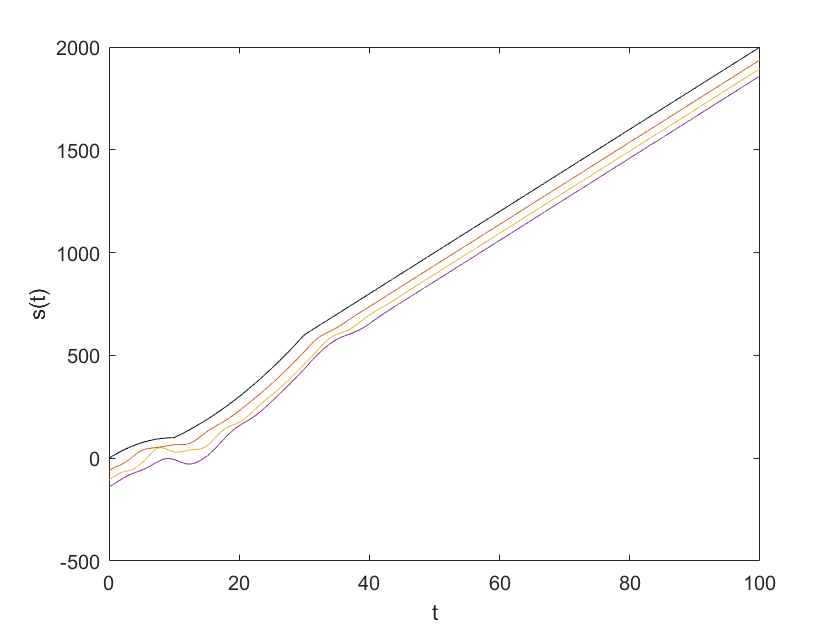




figure(1); clf; hold on; box on;
plot(time,sLead(time),'k');
plot(time,sFollow);
xlabel('t');
ylabel('s(t)');

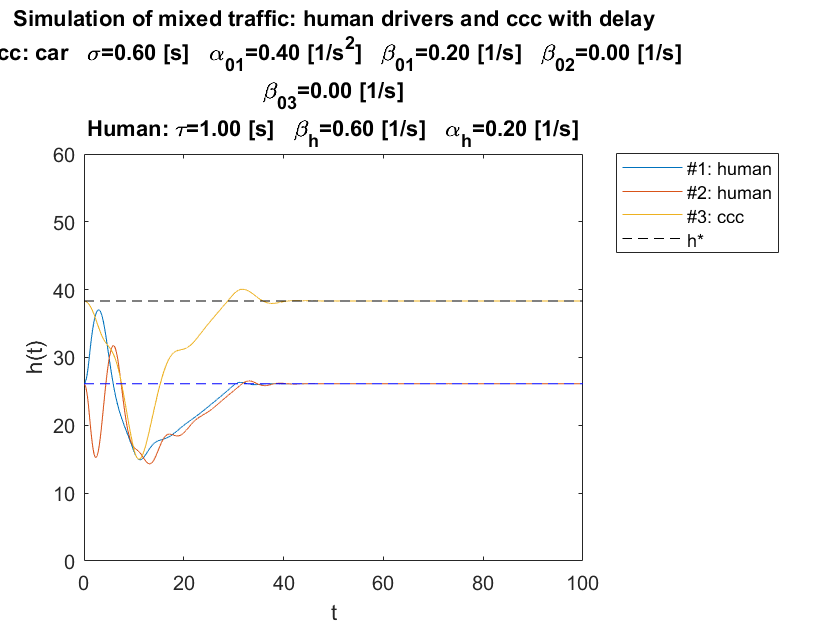


%% Plot of solution
% headways
figure(2); clf; hold on; box on;
plot(time,hFollow);
plot([t0,tend],[h0star,h0star],'k--');
plot([t0,tend],[h1star,h1star],'b--');
axis([t0,tend,hminplot,hmaxplot]);
xlabel('t');
ylabel('h(t)');
title(['Simulation of mixed traffic: human drivers and ccc with delay',10,...
       'ccc: ',vehtype,'   \sigma=',num2str(sigma,'%3.2f'),' [s]   ',...
       '\alpha_0_1=',num2str(alpha01,'%3.2f'),' [1/s^2]   ',...
       '\beta_0_1=',num2str(beta01,'%3.2f'),' [1/s]   ',...
       '\beta_0_2=',num2str(beta02,'%3.2f'),' [1/s]',10,...
       '\beta_0_3=',num2str(beta03,'%3.2f'),' [1/s]',10,...
       'Human: ','\tau=',num2str(tau,'%3.2f'),' [s]   ',...
       '\beta_h=',num2str(betah,'%3.2f'),' [1/s]   ',...
       '\alpha_h=',num2str(alphah,'%3.2f'),' [1/s]']);
driverlegend=cellfun(@(x,y)['#',num2str(x),': ',y],...
             num2cell(1:veh_num),driver,'UniformOutput',false);
legend(horzcat(driverlegend,{'h*'}),'Location','northeastoutside');

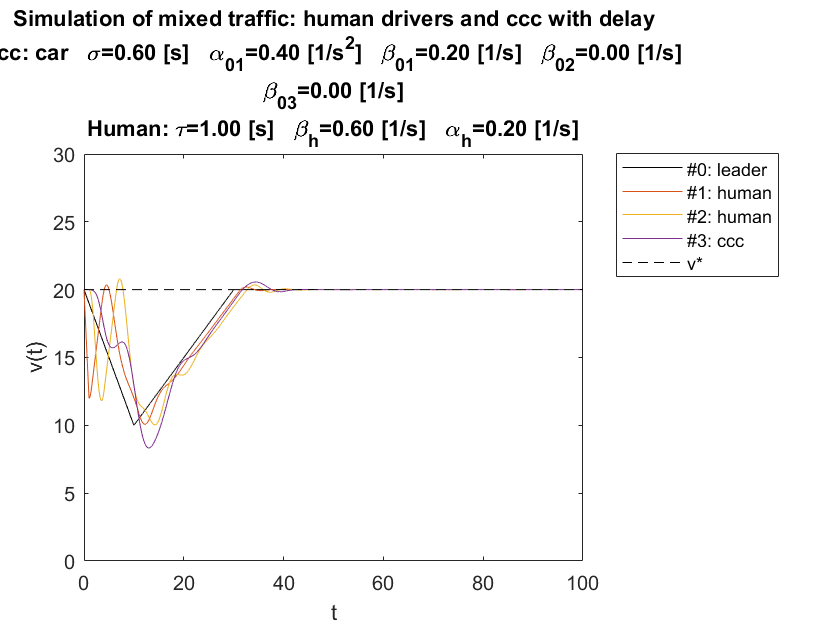


% velocities
figure(3); clf; hold on; box on;
plot(time,vLead(time),'k');
plot(time,vFollow);
plot([t0,tend],[vstar,vstar],'k--');
axis([t0,tend,vminplot,vmaxplot]);
xlabel('t');
ylabel('v(t)');
title(['Simulation of mixed traffic: human drivers and ccc with delay',10,...
       'ccc: ',vehtype,'   \sigma=',num2str(sigma,'%3.2f'),' [s]   ',...
       '\alpha_0_1=',num2str(alpha01,'%3.2f'),' [1/s^2]   ',...
       '\beta_0_1=',num2str(beta01,'%3.2f'),' [1/s]   ',...
       '\beta_0_2=',num2str(beta02,'%3.2f'),' [1/s]',10,...
       '\beta_0_3=',num2str(beta03,'%3.2f'),' [1/s]',10,...
       'Human: ','\tau=',num2str(tau,'%3.2f'),' [s]   ',...
       '\beta_h=',num2str(betah,'%3.2f'),' [1/s]   ',...
       '\alpha_h=',num2str(alphah,'%3.2f'),' [1/s]']);
driverlegend=cellfun(@(x,y)['#',num2str(x),': ',y],...
             num2cell(1:veh_num),driver,'UniformOutput',false);
legend(horzcat({'#0: leader'},driverlegend,{'v*'}),'Location','northeastoutside');